close all
clear
clc
data = readmatrix('sub-06_Sherlock_Mov_DMN_AVG_112_tmseries.xlsx');

%T considered as number of data points analyzed, f as number of brain
%regions 747,885,138
T =138; t = (1:T)/T; Const=0;
f = data(747:885,:)-mean(data(747:885,:),1);

f = f';
Z = gsp_distanz(f').^2;
% we can multiply the pairwise distances with a number to control sparsity
[W] = gsp_learn_graph_log_degrees(Z, 1, 5);

# iters: 1000. Rel primal: 5.0144e-04 Rel dual: 5.0138e-04  OBJ 3.083e+01
Time needed is 0.035499 seconds


% clean up zeros
W(W<1e-5) = 0;
G = gsp_graph(W);


%running MVMD
norm_input=f/max(max(f));
[u, u_hat, omega] = MVMD_ver1(norm_input, 2000, 0, 10, 0, 1, 1e-7);

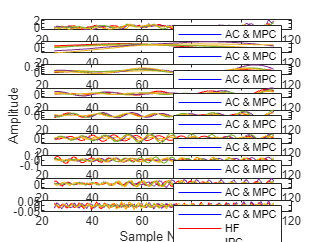

%Testing between regions
c1 = 1;
c2 = 2;
c3 = 3;
c4 = 4;
c5 = 5;
c6 = 1;
c7 = 1;
c8 = 1;
c9 = 1;
c10 = 1; 
figure;
%subplot(611); plot(T*t(:,25:T-25), f(c1, 25:T-25), "blue", T*t(:,25:T-25), f(c2, 25:T-25), 'red') 
%subplot(612); plot(T*t(:,25:T-25), u(1, 25:T-25, c1), "blue", T*t(:,25:T-25), u(1, 25:(T-25), c2), 'red')
%subplot(613); plot(T*t(:,25:T-25), u(2, 25:T-25, c1), "blue", T*t(:,25:T-25), u(2, 25:(T-25), c2), 'red')
%subplot(614); plot(T*t(:,25:T-25), u(3, 25:T-25, c1), "blue", T*t(:,25:T-25), u(3, 25:(T-25), c2), 'red')
%subplot(615); plot(T*t(:,25:T-25), u(4, 25:T-25, c1), "blue", T*t(:,25:T-25), u(4, 25:(T-25), c2), 'red')
%subplot(616); plot(T*t(:,25:T-25), u(5, 25:T-25, c1), "blue", T*t(:,25:T-25), u(5, 25:(T-25), c2), 'red')

subplot(911); plot(T*t(:,25:T-25), f(c1, 25:T-25), "blue", T*t(:,25:T-25), f(c2, 25:T-25), 'red', T*t(:,25:T-25), f(c3, 25:T-25),T*t(:,25:T-25), f(c4, 25:T-25),T*t(:,25:T-25), f(c5, 25:T-25),T*t(:,25:T-25), f(c6, 25:T-25),T*t(:,25:T-25), f(c7, 25:T-25),T*t(:,25:T-25), f(c8, 25:T-25),T*t(:,25:T-25), f(c9, 25:T-25),T*t(:,25:T-25), f(c10, 25:T-25)), legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')
subplot(912); plot(T*t(:,25:T-25), u(1, 25:T-25, c1), "blue", T*t(:,25:T-25), u(1, 25:(T-25), c2), 'red',T*t(:,25:T-25), u(1, 25:T-25, c3),T*t(:,25:T-25), u(1, 25:T-25, c4),T*t(:,25:T-25), u(1, 25:T-25, c5),T*t(:,25:T-25), u(1, 25:T-25, c6),T*t(:,25:T-25), u(1, 25:T-25, c7),T*t(:,25:T-25), u(1, 25:T-25, c8),T*t(:,25:T-25), u(1, 25:T-25, c9),T*t(:,25:T-25), u(1, 25:T-25, c10)),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')
subplot(913); plot(T*t(:,25:T-25), u(2, 25:T-25, c1), "blue", T*t(:,25:T-25), u(2, 25:(T-25), c2), 'red',T*t(:,25:T-25), u(2, 25:T-25, c3),T*t(:,25:T-25), u(2, 25:T-25, c4),T*t(:,25:T-25), u(2, 25:T-25, c5),T*t(:,25:T-25), u(2, 25:T-25, c6),T*t(:,25:T-25), u(2, 25:T-25, c7),T*t(:,25:T-25), u(2, 25:T-25, c8),T*t(:,25:T-25), u(2, 25:T-25, c9),T*t(:,25:T-25), u(2, 25:T-25, c10)),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')
subplot(914); plot(T*t(:,25:T-25), u(3, 25:T-25, c1), "blue", T*t(:,25:T-25), u(3, 25:T-25, c2), 'red',T*t(:,25:T-25), u(3, 25:T-25, c3),T*t(:,25:T-25), u(3, 25:T-25, c4),T*t(:,25:T-25), u(3, 25:T-25, c5),T*t(:,25:T-25), u(3, 25:T-25, c6),T*t(:,25:T-25), u(3, 25:T-25, c7),T*t(:,25:T-25), u(3, 25:T-25, c8),T*t(:,25:T-25), u(3, 25:T-25, c9),T*t(:,25:T-25), u(3, 25:T-25, c10)),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')
subplot(915); plot(T*t(:,25:T-25), u(4, 25:T-25, c1), "blue", T*t(:,25:T-25), u(4, 25:T-25, c2), 'red',T*t(:,25:T-25), u(4, 25:T-25, c3),T*t(:,25:T-25), u(4, 25:T-25, c4),T*t(:,25:T-25), u(4, 25:T-25, c5),T*t(:,25:T-25), u(4, 25:T-25, c6),T*t(:,25:T-25), u(4, 25:T-25, c7),T*t(:,25:T-25), u(4, 25:T-25, c8),T*t(:,25:T-25), u(4, 25:T-25, c9),T*t(:,25:T-25), u(4, 25:T-25, c10)),ylabel('Amplitude'), legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')
subplot(916); plot(T*t(:,25:T-25), u(5, 25:T-25, c1), "blue", T*t(:,25:T-25), u(5, 25:(T-25), c2), 'red',T*t(:,25:T-25), u(5, 25:T-25, c3),T*t(:,25:T-25), u(5, 25:T-25, c4),T*t(:,25:T-25), u(5, 25:T-25, c5),T*t(:,25:T-25), u(5, 25:T-25, c6),T*t(:,25:T-25), u(5, 25:T-25, c7),T*t(:,25:T-25), u(5, 25:T-25, c8),T*t(:,25:T-25), u(5, 25:T-25, c9),T*t(:,25:T-25), u(5, 25:T-25, c10)),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')
subplot(917); plot(T*t(:,25:T-25), u(6, 25:T-25, c1), "blue", T*t(:,25:T-25), u(6, 25:(T-25), c2), 'red',T*t(:,25:T-25), u(6, 25:T-25, c3),T*t(:,25:T-25), u(6, 25:T-25, c4),T*t(:,25:T-25), u(6, 25:T-25, c5),T*t(:,25:T-25), u(6, 25:T-25, c6),T*t(:,25:T-25), u(6, 25:T-25, c7),T*t(:,25:T-25), u(6, 25:T-25, c8),T*t(:,25:T-25), u(6, 25:T-25, c9),T*t(:,25:T-25), u(6, 25:T-25, c10)),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')
subplot(918); plot(T*t(:,25:T-25), u(7, 25:T-25, c1), "blue", T*t(:,25:T-25), u(7, 25:(T-25), c2), 'red',T*t(:,25:T-25), u(7, 25:T-25, c3),T*t(:,25:T-25), u(7, 25:T-25, c4),T*t(:,25:T-25), u(7, 25:T-25, c5),T*t(:,25:T-25), u(7, 25:T-25, c6),T*t(:,25:T-25), u(7, 25:T-25, c7),T*t(:,25:T-25), u(7, 25:T-25, c8),T*t(:,25:T-25), u(7, 25:T-25, c9),T*t(:,25:T-25), u(7, 25:T-25, c10)),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')
subplot(919); plot(T*t(:,25:T-25), u(8, 25:T-25, c1), "blue", T*t(:,25:T-25), u(8, 25:T-25, c2), 'red',T*t(:,25:T-25), u(8, 25:T-25, c3),T*t(:,25:T-25), u(8, 25:T-25, c4),T*t(:,25:T-25), u(8, 25:T-25, c5),T*t(:,25:T-25), u(8, 25:T-25, c6),T*t(:,25:T-25), u(8, 25:T-25, c7),T*t(:,25:T-25), u(8, 25:T-25, c8),T*t(:,25:T-25), u(8, 25:T-25, c9),T*t(:,25:T-25), u(8, 25:T-25, c10)),xlabel('Sample Number'),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')

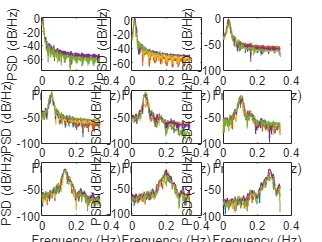

SampleRate = 0.67;
P = 9;
for X = 1:P
[pxx,f] = pwelch(pagetranspose(u(X,:,:)),138,[],[],0.67);

subplot(3,3,X); box on; plot(f,10*log10(pxx))

xlabel('Frequency (Hz)');
ylabel('PSD (dB/Hz)');
end

%Correlation function

similarity_matrix = ConnectivityMatrixTest(u);



% figure
for t = 1:10
similarity_matrix(similarity_matrix<0.001)=0;
%g = similarity_matrix(t,:,:) - diag(diag(similarity_matrix(t,:,:)));
%plotting
temp = similarity_matrix(t,:,:);
temp2(:,1:5) = temp(:,:,1:5);
temp3(:,:,t) = temp2(:,1:5);
temp4(:,:,t) = temp3(:,:,t) - diag(diag(temp3(:,:,t)));
g = graph(temp4(:,:,t));

end
figure('Position',[489, 343, 714, 420])


%nLabels = {'Anterior cingulate and medial prefrontal cortex','Hippocampal formation','Inferior parietal cortex','Lateral Temporal cortex','Posterior cingulate cortex'};
nLabels = {'AC & MPC', 'HF', 'IPC', 'LTC', 'PCC'};
g=graph(temp4(:,:,2));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,1,'Position',[0.05,0.55,0.45,0.35]); s1=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});

edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s1.EdgeCData = g.Edges.EdgeColors;
colormap(jet); caxis auto
colorbar
title('c_2 Connectivity','FontSize',14)

g=graph(temp4(:,:,3));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,2,'Position',[0.525,0.55,0.45,0.35]); s2=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});

edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s2.EdgeCData = g.Edges.EdgeColors;
colormap(jet); caxis auto
colorbar
title('c_3 Connectivity','FontSize',14)

g=graph(temp4(:,:,4));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,3,'Position',[0.05,0.1,0.45,0.35]); s3=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});

edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s3.EdgeCData = g.Edges.EdgeColors;
colormap(jet); caxis auto
colorbar
title('c_4 Connectivity','FontSize',14)

g=graph(temp4(:,:,5));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,4,'Position',[0.525,0.1,0.45,0.35]);s4=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});

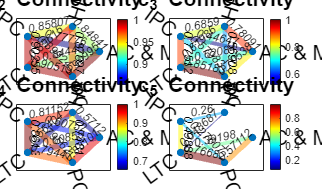

edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s4.EdgeCData = g.Edges.EdgeColors;
colormap(jet); caxis auto
colorbar
title('c_5 Connectivity','FontSize',14)

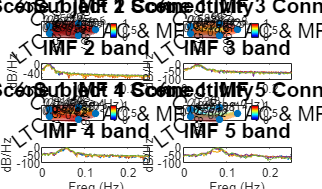

% figure
for t = 1:10
similarity_matrix(similarity_matrix<0.001)=0;
%g = similarity_matrix(t,:,:) - diag(diag(similarity_matrix(t,:,:)));
%plotting
temp = similarity_matrix(t,:,:);
temp2(:,1:5) = temp(:,:,1:5);
temp3(:,:,t) = temp2(:,1:5);
temp4(:,:,t) = temp3(:,:,t) - diag(diag(temp3(:,:,t)));
g = graph(temp4(:,:,t));

end
figure('Position',[489, 343, 714, 420])


%nLabels = {'Anterior cingulate and medial prefrontal cortex','Hippocampal formation','Inferior parietal cortex','Lateral Temporal cortex','Posterior cingulate cortex'};
nLabels = {'AC & MPC', 'HF', 'IPC', 'LTC', 'PCC'};
g=graph(temp4(:,:,2));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(4,2,1); s1=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s1.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Subject 1 Scene 1 IMF 2 Connectivity','FontSize',14)

g=graph(temp4(:,:,3));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(4,2,2); s2=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s2.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Subject 1 Scene 1 IMF 3 Connectivity','FontSize',14)

[pxx,f] = pwelch(pagetranspose(u(2,:,:)),138,[],[],0.67);
subplot(4,2,3); s3=plot(f,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 0.25]);
title('IMF 2 band','FontSize',14)

[pxx,f] = pwelch(pagetranspose(u(3,:,:)),138,[],[],0.67);
subplot(4,2,4);s4=plot(f,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 0.25]);
title('IMF 3 band','FontSize',14)

g=graph(temp4(:,:,4));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(4,2,5); s1=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s1.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Subject 1 Scene 1 IMF 4 Connectivity','FontSize',14)

g=graph(temp4(:,:,5));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(4,2,6); s2=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s2.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Subject 1 Scene 1 IMF 5 Connectivity','FontSize',14)

[pxx,f] = pwelch(pagetranspose(u(4,:,:)),138,[],[],0.67);
subplot(4,2,7); s3=plot(f,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 0.25]);
title('IMF 4 band','FontSize',14)

[pxx,f] = pwelch(pagetranspose(u(5,:,:)),138,[],[],0.67);
subplot(4,2,8);s4=plot(f,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 0.25]);
title('IMF 5 band','FontSize',14)

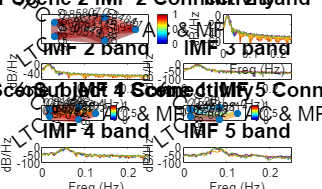

%nLabels = {'Anterior cingulate and medial prefrontal cortex','Hippocampal formation','Inferior parietal cortex','Lateral Temporal cortex','Posterior cingulate cortex'};
nLabels = {'AC & MPC', 'HF', 'IPC', 'LTC', 'PCC'};
g=graph(temp4(:,:,2));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(4,3,[1,2]); s1=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s1.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Subject 1 Scene 2 IMF 2 Connectivity','FontSize',14)

[pxx,f] = pwelch(pagetranspose(u(2,:,:)),138,[],[],0.67);
subplot(4,3,3); s3=plot(f,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 0.25]);
title('IMF 2 band','FontSize',14)

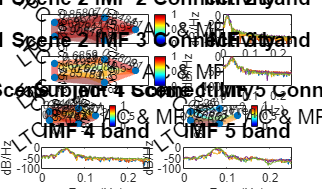


g=graph(temp4(:,:,3));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(4,3,[4,5]); s2=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s2.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Subject 1 Scene 2 IMF 3 Connectivity','FontSize',14)

[pxx,f] = pwelch(pagetranspose(u(3,:,:)),138,[],[],0.67);
subplot(4,3,6);s4=plot(f,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 0.25]);
title('IMF 3 band','FontSize',14)

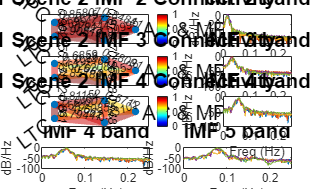


g=graph(temp4(:,:,4));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(4,3,[7,8]); s1=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s1.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Subject 1 Scene 2 IMF 4 Connectivity','FontSize',14)

[pxx,f] = pwelch(pagetranspose(u(4,:,:)),138,[],[],0.67);
subplot(4,3,9); s3=plot(f,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 0.25]);
title('IMF 4 band','FontSize',14)

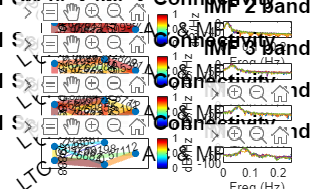


g=graph(temp4(:,:,5));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(4,3,[10,11]); s2=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s2.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Subject 1 Scene 2 IMF 5 Connectivity','FontSize',14)

[pxx,f] = pwelch(pagetranspose(u(5,:,:)),138,[],[],0.67);
subplot(4,3,12);s4=plot(f,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 0.25]);
title('IMF 5 band','FontSize',14)

%nLabels = {'Anterior cingulate and medial prefrontal cortex','Hippocampal formation','Inferior parietal cortex','Lateral Temporal cortex','Posterior cingulate cortex'};
nLabels = {'AC & MPC', 'HF', 'IPC', 'LTC', 'PCC'};
g=graph(temp4(:,:,2));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,1,1,'Position',[0.05,0.5,0.45,0.45]); s1=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});

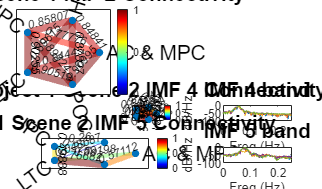

edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s1.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Subject 9 Scene 1 IMF 2 Connectivity','FontSize',14)


g=graph(temp4(:,:,2));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
[pxx,freq] = pwelch(pagetranspose(u(2,:,:)),100,0,1024,SampleRate);
subplot(2,1,2,'Position',[0.05,0.3,0.45,0.15]); s3=plot(freq,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 100]);

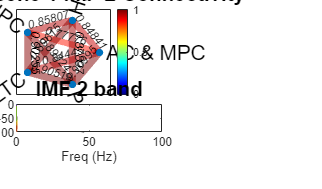

title('IMF 2 band','FontSize',14)

%Sliding window start
for n = 1:9
    for h = 1:10
        for i = 1:5
            u2(h,1:100,i,n)= u(h, 100*n-100+1:n*100, i);
        end
    end
end

Index in position 2 exceeds array bounds. Index must not exceed 139.

% Create plots for comparison of u2 and u

%plot(u2(FreqBand,SliceSize,RegionNR,sliceNR)

%plot(u(FreqBand,timesample,RegionNR))

t = tiledlayout(2,2);
nexttile
plot(u2(2,:,4,1))
nexttile
plot(u(2,1:100,4))

similarity_matrix_slide = ConnectivityMatrixTestSlide(u2)

%Similarity_matrix_slide(langs med, ned ad, region nr, slice nr) 

% figure sliding window

similarity_matrix_slide(similarity_matrix_slide<0.001)=0;
%g = similarity_matrix(t,:,:) - diag(diag(similarity_matrix(t,:,:)));
%plotting
% similarity_matrix_slide(FreqComp,N,N,SliceNR)

temp_slide(:,:,:,:) = similarity_matrix_slide(:,:,:,:);


for t = 1:10
    for l = 1:9
        g = graph(squeeze(temp_slide(t,:,:,l)));
    end
end


figure('Position',[489, 343, 714, 420])


%nLabels = {'Anterior cingulate and medial prefrontal cortex','Hippocampal formation','Inferior parietal cortex','Lateral Temporal cortex','Posterior cingulate cortex'};
nLabels = {'AC & MPC', 'HF', 'IPC', 'LTC', 'PCC'};

g=graph(squeeze(temp_slide(2,:,:,1)));
g = rmedge(g, 1:numnodes(g), 1:numnodes(g));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
edge_strength = g.Edges.Weight;
subplot(3,3,1); s1=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 10); xticklabels({}); yticklabels({});
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s1.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('slice 1 Connectivity','FontSize',14)

g=graph(squeeze(temp_slide(2,:,:,2)));
g = rmedge(g, 1:numnodes(g), 1:numnodes(g));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(3,3,2); s2=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 10); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s2.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('slice 2 Connectivity','FontSize',14)

g=graph(squeeze(temp_slide(2,:,:,4)));
g = rmedge(g, 1:numnodes(g), 1:numnodes(g));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(3,3,3); s3=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 10); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s3.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('slice 3 Connectivity','FontSize',14)

g=graph(squeeze(temp_slide(2,:,:,5)));
g = rmedge(g, 1:numnodes(g), 1:numnodes(g));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(3,3,4);s4=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 10); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s4.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('slice 4 Connectivity','FontSize',14)

g=graph(squeeze(temp_slide(2,:,:,5)));
g = rmedge(g, 1:numnodes(g), 1:numnodes(g));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(3,3,5);s4=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 10); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s4.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('slice 5 Connectivity','FontSize',14)

g=graph(squeeze(temp_slide(2,:,:,6)));
g = rmedge(g, 1:numnodes(g), 1:numnodes(g));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(3,3,6);s4=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 10); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s4.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('slice 6 Connectivity','FontSize',14)

g=graph(squeeze(temp_slide(2,:,:,7)));
g = rmedge(g, 1:numnodes(g), 1:numnodes(g));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(3,3,7);s4=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 10); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s4.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('slice 7 Connectivity','FontSize',14)

g=graph(squeeze(temp_slide(2,:,:,8)));
g = rmedge(g, 1:numnodes(g), 1:numnodes(g));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(3,3,8);s4=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 10); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s4.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('slice 8 Connectivity','FontSize',14)

g=graph(squeeze(temp_slide(2,:,:,9)));
g = rmedge(g, 1:numnodes(g), 1:numnodes(g));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(3,3,9);s4=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 10); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s4.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('slice 9 Connectivity','FontSize',14)
